# Comandos Scilab

Nesta seção, são abordados alguns problemas associados a Sistemas de Controle. Considera-se a configuração padrão do sistema realimentado da Fig. 01.

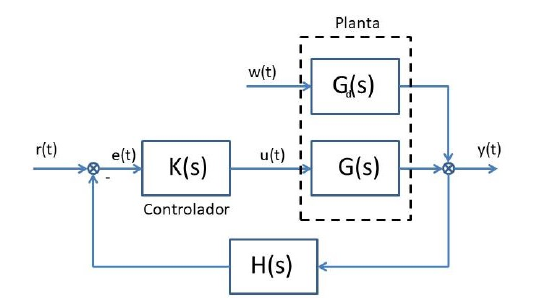

## PROBLEMAS:

Seja o sistema de controle da Fig. 01 com as funções de transferência dadas a seguir e $G_d(s) = 0$:


$$$$G(s)=\frac{s^2 + s + 2}{s(s + 5)(s^2 + 2s + 1)}$$ $$H(s)=1$$ $$K(s)=\frac{20s + 0.01}{s}$$$$


- 1) Obter a função de transferência de malha-fechada resultante; 

- 2) Calcular uma representação no espaço de estados para a planta, O controlador e o sistema em malha-fechada; 

- 3) Analisar a estabilidade do sistema em malha-fechada utilizando a função de transferência e o modelo no espaço de estados. Encontrar o polinômio caracterı́stico do sistema resultante;

- 4) Obter os sinais de saı́da y(t) e controle u(t) do sistema em malha fechada para a entrada r(t) o degrau unitário e o impulso unitário. Determinar o maior pico do sinal de saı́da e o tempo que a saı́da leva para atingir 98% do regime permanente, para r(t) = 1; 

- 5) Calcular a saı́da do sistema em malha-fechada para as entradas r(t) = sen(πt) e r(t) uma onda quadrada de amplitude unitária e perı́odo igual a quatro; 

- 6) Analisar a controlabilidade e a observabilidade da planta a ser controlada (G(s)) e obter a forma de Jordan associada à matriz dinâmica (planta);

- 7) Com $G_d(s) =\frac{1}{s^2 +s+1}$ , obter a resposta em frequência entre a saı́da y e a perturbaçaõ w ; 

- 8) O controlador K(s) é substituı́do pelo controlador digital $K(z)$ com o segurador de ordem zero (ZOH), conforme a Fig. 02. Obter o modelo discreto para a planta e ZOH (visto pelo controlador) e, em seguida, calcular a função de transferência discreta de malha-fechada. Calcular a resposta ao degrau unitário e analisar a estabilidade do sistema resultante de malha-fechada. O perı́odo de amostragem é $T_s = 0.01s$ e $K(z) = \frac{0.473z - 0.4728}{z-1}$

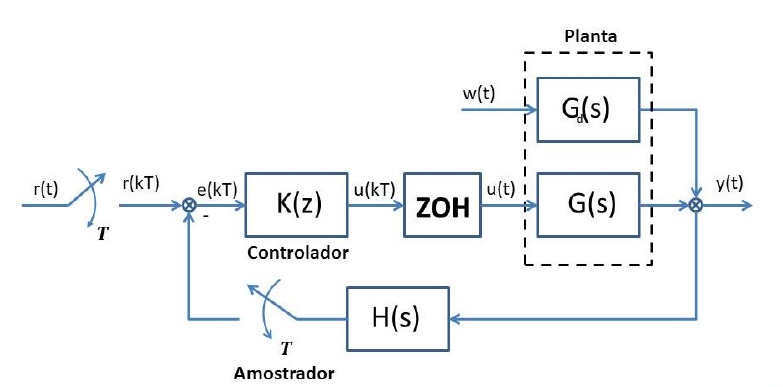

### Problema 1:

Primeiro vamos determinar G(s):

num = [1 1 2]; 
den = conv([1,5,0],[1,2,1]); 
G = tf(num,den)

G =
 
         s^2 + s + 2
  --------------------------
  s^4 + 7 s^3 + 11 s^2 + 5 s
 
Continuous-time transfer function.



Agora o H(s):

H = tf(1,1)

H =
 
  1
 
Static gain.



E por fim o K(s)

K = tf([20 0.01],[1 0])

K =
 
  20 s + 0.01
  -----------
       s
 
Continuous-time transfer function.



Vamos agora obter a função transferência equivalente do bloco G e K em série:

FS = series(G,K)

FS =
 
  20 s^3 + 20.01 s^2 + 40.01 s + 0.02
  -----------------------------------
     s^5 + 7 s^4 + 11 s^3 + 5 s^2
 
Continuous-time transfer function.



Por conta da realimentação, a equação que define o circuito da malha fechada é $\frac{GK}{1+GK}$

MF = feedback(FS,H,-1)

MF =
 
         20 s^3 + 20.01 s^2 + 40.01 s + 0.02
  -------------------------------------------------
  s^5 + 7 s^4 + 31 s^3 + 25.01 s^2 + 40.01 s + 0.02
 
Continuous-time transfer function.



Para obter o numerador e o denominador da função transferência de malha fechada:

[num_mf,den_mf] = tfdata(MF)

num_mf = 1×1 cell array
    {[0 0 20 20.0100 40.0100 0.0200]}


den_mf = 1×1 cell array
    {[1 7 31 25.0100 40.0100 0.0200]}


Agora este objeto é guardado em forma de célula, para isso, deve ser convertido para matriz:

num_mf = cell2mat(num_mf)

num_mf =          0         0   20.0000   20.0100   40.0100    0.0200


den_mf = cell2mat(den_mf)

den_mf =     1.0000    7.0000   31.0000   25.0100   40.0100    0.0200


Para saber as raízes, podemos usar a função `roots:`

roots(num_mf)

ans =   -0.5000 + 1.3229i
  -0.5000 - 1.3229i
  -0.0005 + 0.0000i


roots(den_mf)

ans =   -3.2077 + 3.9247i
  -3.2077 - 3.9247i
  -0.2921 + 1.2130i
  -0.2921 - 1.2130i
  -0.0005 + 0.0000i


Uma função útil para ver os pólos e zeros:

zpk(MF)

ans =
 
                 20 (s+0.0005) (s^2 + s + 2)
  ---------------------------------------------------------
  (s+0.0005) (s^2 + 0.5841s + 1.557) (s^2 + 6.415s + 25.69)
 
Continuous-time zero/pole/gain model.



## Problema 2